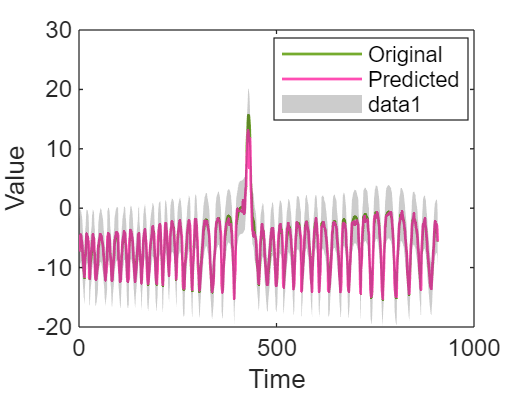

% Imputation via FPRM
ss=PhaSpaRecon(y(:,2),3,5);% Input embedding dimension and time delay
YX=ss';% Reconstruction from complete time series

ss2=PhaSpaRecon(y(:,1),3,5);% Phase space reconstruction, last parameter is embedding dimension
YY=ss2';% Reconstruction from incomplete time series
X=YX;% Predictor matrix 
Y=YY;% Target series with missing segments

rng('shuffle')% Non-fixed random seed for each run
N=length(Y);
cvp = cvpartition(N,'Holdout',0.5);% Set missing point ratio
idxTrn = training(cvp); % Training set indices
idxTest = test(cvp);    % Test (missing) set indices

Xtrain = X(idxTrn,:);
Ytrain = Y(idxTrn,1);
[Ztrain,tr_mu,tr_sigma] = zscore(Xtrain); % Standardize training data
tr_sigma(tr_sigma==0) = 1;

Mdl = fitrgp(Ztrain,Ytrain);

Xtest = X(idxTest,:);
Ztest = (Xtest-tr_mu)./tr_sigma; % Standardize test data
Ytest = Y(idxTest,1);
YFit = predict(Mdl,Ztest);

L = loss(Mdl,Ztest,Ytest);% Calculate loss (MSE)
LL=(L^0.5)./std(Ytest);
YY=[YFit Ytest];
CO=corr(YY);
RERROR=(Ytest-YFit)./YFit;
RERROR1=abs(RERROR);
Re=mean(RERROR1);% Mean relative error
MAE=mean(abs(Ytest-YFit));% Mean absolute error

% Plot results
plot(Ytest,'-','Color',[0.46,0.67,0.18],'LineWidth',1); hold on; 
plot(YFit,'-','Color',[1,0.3,0.7],'LineWidth',1);

xlabel('Time')
ylabel('Value')
legend('Original','Predicted','Location','best')

STD=std(Ytest);
xy=1:1:length(Ytest(:,1)-1);
xy=xy';
y1=Ytest-std(Ytest);
y2=Ytest+std(Ytest);
Yy=[y1 y2];
patch([xy;flipud(xy)],[Yy(:,1);flipud(Yy(:,2))],'k','FaceAlpha',0.2,'EdgeAlpha',0) 